N1

Полярное разложение линейных операторов

fprintf("Матрица линейного оператора:");

Матрица линейного оператора:

A = randi([-10, 10], 2,2)/10

A =     0.8000         0
    0.9000         0


[U, S, V] = svd(A);
B = U * V';
C = V * S * V';
unit = all(all(int8(B*B') == eye(2)));
fprintf("B - унитарная матрица: %d", unit);

B - унитарная матрица: 1

ermit = all(diag(C == C.'));
fprintf("C - эрмитова положительно полуопределённая\nматрица: %d", ermit);

C - эрмитова положительно полуопределённая
матрица: 1

hF3=figure('NumberTitle','off','Name',...
    'The oscillations of string','Color',[0 1 0]);
hA3=axes('Parent',hF3,'Units','pixels');
%axis([-1 1 -1 1]);
vec = rand(2,1);
hold on;
grid();
x = [0, vec(1,1)];
y = [0, vec(2,1)]

y =          0    0.9001


plot(hA3, x, y);
text(x, y, 'Original vector');
vecB = B * vec;
x = [0, vecB(1,1)];
y = [0, vecB(2,1)]

y =          0    0.8504


plot(hA3, x, y);
text(x, y, 'Rotated vector');
vecC = C * vecB;
x = [0, vecC(1,1)];
y = [0, vecC(2,1)]

y =      0     0


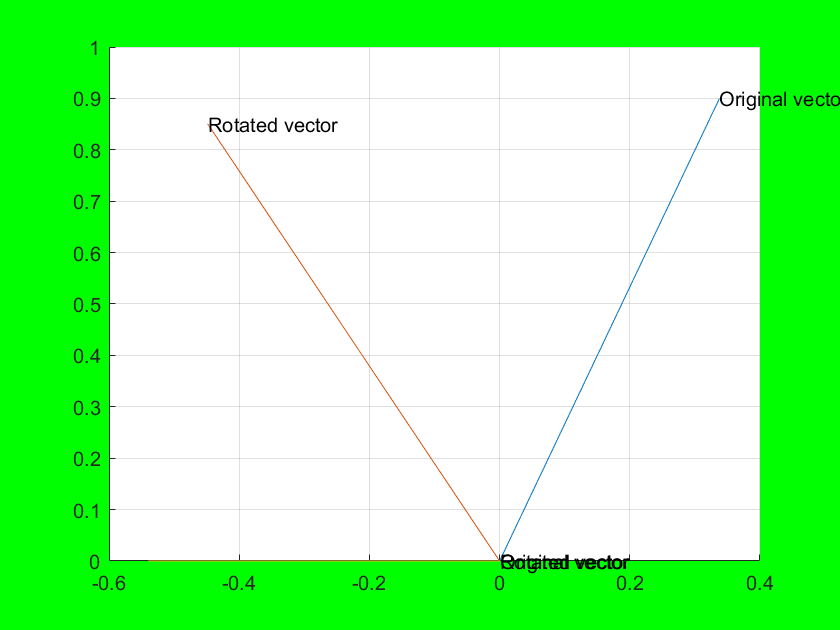

plot(hA3, x, y);
%text(vecC(1,1), vecC(2,1), 'Rotated vector');
hold off;

function [x,y] = getEllipse(rx,ry)
phi = atan(rx(2,1)/rx(1,1))
beta = linspace(0,2*pi,100);
x_len = sqrt(rx(1,1)^2 + rx(2,1)^2)
y_len = sqrt(ry(1,1)^2 + ry(2,1)^2)
x = x_len*cos(beta-phi)
y = y_len*sin(beta-phi)
end


N2

Сингулярное разложение